# **Fundamentals of Robotics**

**Introduction to Robotics Modeling and Control**

clear;
close all;
format compact;

## Forward Kinematics: Denavit-Hartenberg Convention

#### EXAMPLE 1. Two Link Planar Robot Manipulator

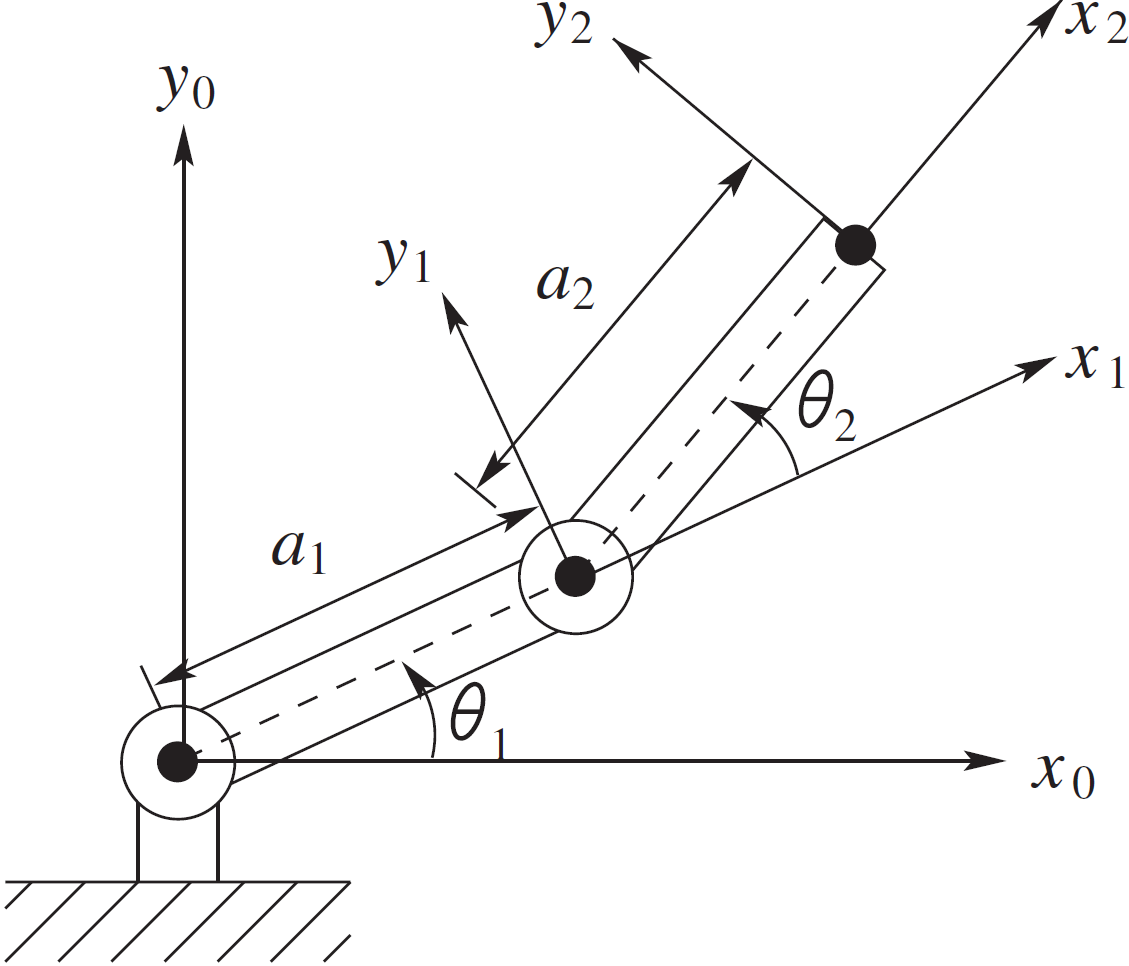

**DH Parameter Table:**

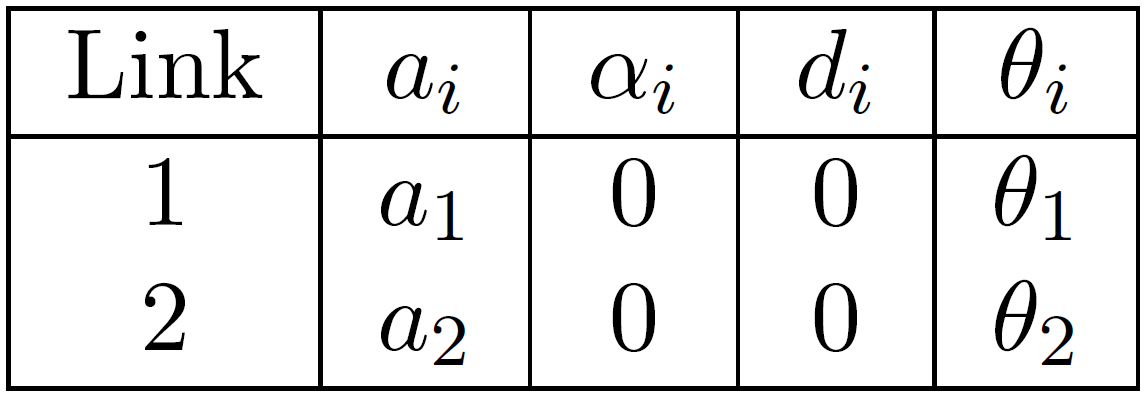

link1 = RevoluteLink(0, 1.25, 0, 0, 'name', 'link1');   % LINK1:    d=0, a=1, alpha=0, *theta + offset=0
link2 = RevoluteLink(0, 1.25, 0, 0, 'name', 'link2');   % LINK2:    d=0, a=1, alpha=0, *theta + offset=0

% Serial Link Manipulator
% 2-DOF (RR) Planar Robot
robot = SerialLinkManipulator([link1, link2], 'name', '2-DOF RR Planar Robot');

theta1 =-45;
theta2 =45;

robot.links(1).theta = deg2rad(theta1);
robot.links(2).theta = deg2rad(theta2);

robot.dh

ans =    -0.7854         0    1.2500         0
    0.7854         0    1.2500         0


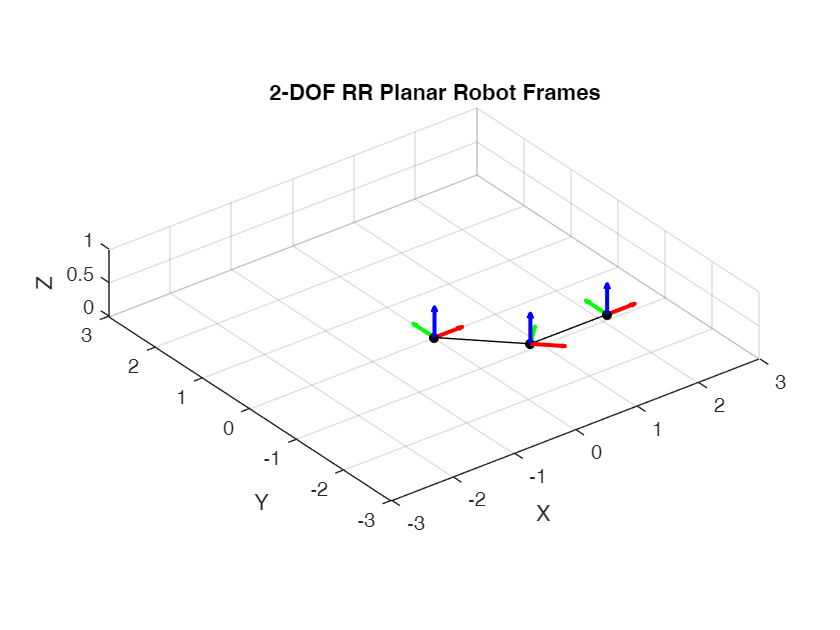

hold on;
plot([robot.jointPose(1,:), robot.x(1)], [robot.jointPose(2,:), robot.x(2)], 'k-');
plotHomogFrames(robot.homogtf, 'Scale', 0.5, 'ArrowStyle', 'arrow'); 

title('2-DOF RR Planar Robot Frames');
xlim([-3, 3]); 
ylim([-3, 3]); 
zlim([0, 1]);